Generating Superellipses

clear;
% Define parameters for the superellipses (a, b, n, center_x, center_y, theta)
    superellipses = [
        2, 1, 0.3, 5, 2, pi/3;
        1.5, 2, 0.5, -1, -1, pi/6;
        4, 3, 0.8, 7, -10, -pi/6;
        0.5, 3, 1.2, 11, 0, pi/12;
        3, 2, 0.6, 0, 8, -0.7*pi;
        2, 3, 0.1, 15, 20, -0.2*pi;
        1, 5, 1, -15, -10, 0.3*pi;
        1.5, 1, 1.3, -4, -6, 0.5*pi;
        1.8, 4, 1.5, -10, 15, 0.6*pi;
        3, 4, 1.8, 20, 6, 0.8*pi;
        4, 2, 1.6, 19, -7, 0.2*pi;
    ];

Params = matrix_cell(superellipses);

Making the Voronoi diagram

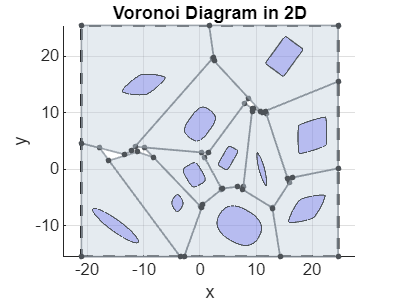

tic
[polyhedrons] = voronoi_diagram_2D(Params);

disp("Time Taken to make voronoi diagram : "+toc)

Time Taken to make voronoi diagram : 0.45298


Making the graph from diagram

Graph is fully connected.


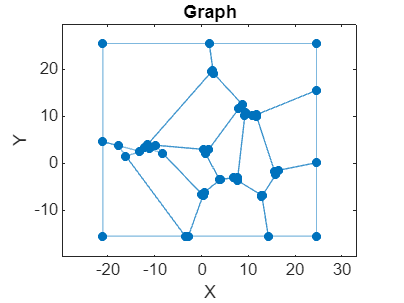

The graph is connected.


tic
vertexGraph = Copy_of_createVoronoiGraph(polyhedrons);

disp("Time Taken to make voronoi graph : "+toc)

Time Taken to make voronoi graph : 0.22781


Shortest Path between nodes on the graph

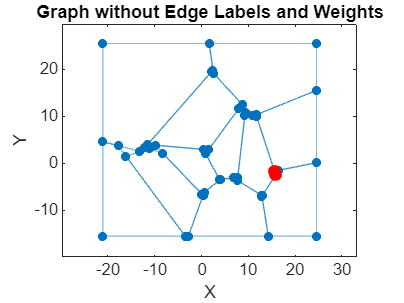


% Plot the graph without node and edge labels
figure;
h = plot(vertexGraph, 'XData', vertexGraph.Nodes.X, 'YData', vertexGraph.Nodes.Y);
h.NodeLabel = {};  % Remove node labels
h.EdgeLabel = {};  % Remove edge labels
title('Graph without Edge Labels and Weights');
xlabel('X');
ylabel('Y');
axis equal;

% Specify start and end nodes for the shortest path
startNode = 44;
endNode = 43;

% Find the shortest path using the graph's weights
[shortestPathIDs, totalDistance] = shortestpath(vertexGraph, startNode, endNode);

% Highlight the shortest path if it exists
if ~isempty(shortestPathIDs)
    hold on;
    % Highlight the nodes in the shortest path
    highlight(h, shortestPathIDs, 'NodeColor', 'r', 'Marker', 'o', 'MarkerSize', 6);
    
    % Highlight the edges in the shortest path
    for i = 1:length(shortestPathIDs)-1
        edgeIdx = findedge(vertexGraph, shortestPathIDs(i), shortestPathIDs(i+1));
        highlight(h, 'Edges', edgeIdx, 'EdgeColor', 'r', 'LineWidth', 2);
    end
    hold off;
else
    disp('No shortest path found.');
end


% Optionally display the total distance
disp(['Total distance of the shortest path: ', num2str(totalDistance)]);

Total distance of the shortest path: 0.82884


% Assume you already have the list of nodes along the path (e.g., from shortestpath function)
pathNodes = [1,2,3,20];  % Replace with actual node IDs along the path

% Initialize total distance
totalDistance = 0;

% Loop through each pair of consecutive nodes in the path
for i = 1:length(pathNodes)-1
    % Find the edge index between consecutive nodes
    edgeIdx = findedge(vertexGraph, pathNodes(i), pathNodes(i+1));
    
    % If the edge exists, add its weight to the total distance
    if edgeIdx > 0
        totalDistance = totalDistance + vertexGraph.Edges.Weight(edgeIdx);
    else
        error('Edge between nodes %d and %d does not exist!', pathNodes(i), pathNodes(i+1));
    end
end

Shortest path between any two points

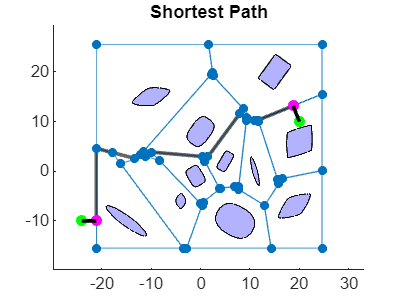

close all;
startPoint = [-24,-10];endPoint = [20,10];
[updatedGraph,pathCoords] = ShortestPath(vertexGraph, startPoint, endPoint,Params);
axis equal

## Planning for extended robot using minkowski sum

Computing the minkowski sum with a small square shaped robot and then fitting superellipses on the minkowski sums

% hold off
% small_square_params = [0.6, 0.9, 0.1, 0, 0, 0];
% % Define parameters for the superellipses (a, b, n, center_x, center_y, theta)
% superellipses = [
%         2, 1, 0.3, 5, 2, pi/3;
%         1.5, 2, 0.5, -1, -1, pi/6;
%         4, 3, 0.8, 7, -10, -pi/6;
%         0.5, 3, 1.2, 11, 0, pi/12;
%         3, 2, 0.6, 0, 8, -0.7*pi;
%         2, 3, 0.1, 15, 20, -0.2*pi;
%         1, 5, 1, -15, -10, 0.3*pi;
%         1.5, 1, 1.3, -4, -6, 0.5*pi;
%         1.8, 4, 1.5, -10, 15, 0.6*pi;
%         3, 4, 1.8, 20, 6, 0.8*pi;
%         4, 2, 1.6, 19, -7, 0.2*pi;
%     ];
% 
% % Initialize storage for Minkowski sums
% minkowski_sums = cell(size(superellipses, 1), 1);
% numPoints = 100;
% s2 = SuperEllipse([small_square_params(1:3),0,small_square_params(4:5),small_square_params(6),numPoints]);
% % Compute Minkowski sums for each superellipse
% for i = 1:size(superellipses, 1)
% 
%     % Create SuperEllipse object
%     s1 = SuperEllipse([superellipses(i, 1:3),0,superellipses(i, 4:5),0,numPoints]);
% 
%     % Compute Minkowski sum
%     angles = [superellipses(i, 6),0];
%     shears = [0,0];
%     M1 = rot2(angles(1)) * [1, shears(1); 0, 1];
%     M2 = rot2(angles(2)) * [1, shears(2); 0, 1];
%     minkowski_sums{i} = MinkSumClosedForm(s1, s2, M1, M2).GetMinkSumFromGradient(s1.GetGradientsCanonical());
% end
% 
% % Fitting superellipses (n,a,b,angle,h,k)
% superellipses_mink = zeros(size(superellipses));
% for i = 1:size(superellipses, 1)
%      x = EMS2D(minkowski_sums{i},'OutlierRatio',0.0001);
%      superellipses_mink(i,1:2) = x(2:3);
%      superellipses_mink(i,3) = x(1);
%      superellipses_mink(i,4:5) = superellipses(i,4:5);
%      superellipses_mink(i,6) = x(4);
% end
% Params_mink = matrix_cell(superellipses_mink);

% [polyhedrons_mink] = voronoi_diagram_2D(Params_mink);

% thresholdDistance = 0.7;
% vertexGraph_mink = createVoronoiGraph(polyhedrons_mink, thresholdDistance);

Shortest path between any two points

% startPoint = [-24,-10];endPoint = [20,10];
% ShortestPath(vertexGraph_mink, startPoint, endPoint,Params_mink)
% small_square_params1 = small_square_params;small_square_params2 = small_square_params;
% small_square_params1(4:5) = startPoint;small_square_params2(4:5) = endPoint;
% Params_robot = matrix_cell([small_square_params1;small_square_params2]);
% plot_multiple_superellipses(Params,'r')
% plot_multiple_superellipses(Params_robot,'g')